clc;
clear;
close all;

%% Parameters
Nt = 2;  
Nr = 2;  
N_fft = 64;                     
cp_len = 2;                   
modOrder = 2;                  
bitsPerSymbol = log2(modOrder);
num_pilots = 4; 
num_symbols = N_fft - num_pilots - 1; 
numBits = 50 * Nt * num_symbols

numBits = 5900

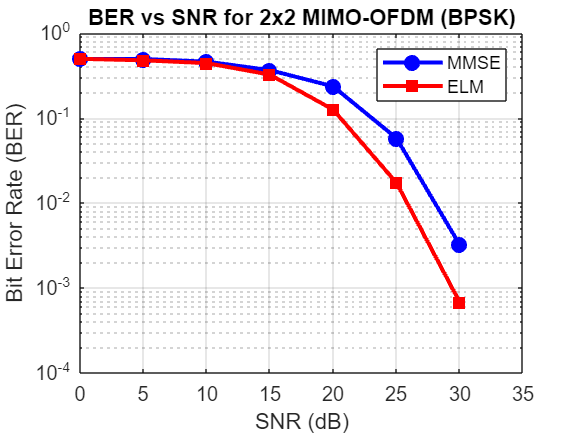

fs = 5e6;                     
fd = 50;                      
Pt = 1;                      
time_stamps = numBits / (Nt * num_symbols);
SNR_dB = 0:5:35;              
BER_MMSE = zeros(size(SNR_dB));
BER_ELM = zeros(size(SNR_dB));

% ELM Parameters
L = 4;                  % Number of hidden nodes
alpha = 0.01;           % Regularization
activation = @(x) 1./(1+exp(-x)); % Sigmoid
W = unifrnd(-1,1,L,2*Nr); % Random weights
B = unifrnd(-1,1,L,1);    % Random biases

% All possible BPSK MIMO symbol vectors
X_P = [1 1; 1 -1; -1 1; -1 -1].';

%% Generate random bits
bits = randi([0 1], numBits, 1);
symbols = 2 * bits - 1;  % BPSK mapping

%% MIMO Channel Object
rayleighChan = comm.MIMOChannel( ...
    'FadingDistribution', 'Rayleigh', ...
    'SampleRate', fs, ...
    'PathDelays', 0, ...
    'AveragePathGains', 0, ...
    'MaximumDopplerShift', fd, ...
    'NumTransmitAntennas', Nt, ...
    'NumReceiveAntennas', Nr, ...
    'SpatialCorrelationSpecification', 'None', ...
    'RandomStream', 'mt19937ar with seed', ...
    'Seed', 42);

%% Loop over SNR values
for snr_idx = 1:length(SNR_dB)
    snr_linear = 10^(SNR_dB(snr_idx)/10);
    noise_variance = Pt / snr_linear;  
    noise_std = sqrt(noise_variance/2);

    % --- Transmitter Side ---
    ofdm_symbols = zeros(N_fft, Nt, time_stamps);
    ofdm_no_pilot_symbols = pagetranspose(reshape(symbols, Nt, num_symbols, []));
    
    % Insert orthogonal pilots
    ofdm_symbols(1,1,:) = 1;    ofdm_symbols(1,2,:) = 1;
    ofdm_symbols(2,1,:) = 1;    ofdm_symbols(2,2,:) = -1;
    ofdm_symbols(3,1,:) = -1;   ofdm_symbols(3,2,:) = -1;
    ofdm_symbols(4,1,:) = -1;    ofdm_symbols(4,2,:) = 1;

    % Insert data
    k = (N_fft/2) - num_pilots;
    for i = 1:time_stamps
        ofdm_symbols(num_pilots+1:N_fft/2,:,i) = ofdm_no_pilot_symbols(1:k,:,i);
        ofdm_symbols(N_fft/2+2:end,:,i) = ofdm_no_pilot_symbols(k+1:end,:,i);
    end

    % IFFT
    ofdm_symbols_time = ifft(ofdm_symbols, N_fft);

    % Add CP
    ofdm_symbols_cp = cat(1, ofdm_symbols_time(end-cp_len+1:end,:,:), ofdm_symbols_time);
    txFrame = sqrt(Pt) * ofdm_symbols_cp;

    detected_MMSE = zeros(size(ofdm_no_pilot_symbols));
    detected_ELM = zeros(size(ofdm_no_pilot_symbols));

    for i = 1:time_stamps
        % --- Channel ---
        H_actual = (randn(Nr,Nt)+1j*randn(Nr,Nt))/sqrt(2); 
        rxFrame = zeros(size(txFrame(:,:,i)));
        for n = 1:N_fft+cp_len
            rxFrame(n,:) = rayleighChan(txFrame(n,:,i));
        end

        % --- Add Noise ---
        noise = noise_std*(randn(size(rxFrame)) + 1i*randn(size(rxFrame)));
        rxFrame = rxFrame + noise;

        % --- Receiver ---
        rxFrame_no_cp = rxFrame(cp_len+1:end, :);
        rxFrame_freq = fft(rxFrame_no_cp, N_fft);

        % --- Channel Estimation using pilots ---
        Y_pilot = rxFrame_freq(1:4,:);   
        X_pilot = ofdm_symbols(1:4,:,i);
        H_est = (pinv(X_pilot) * Y_pilot).'; 

        % --- Data detection ---
        data_idx = [num_pilots+1:N_fft/2, N_fft/2+2:N_fft];
        rx_data = rxFrame_freq(data_idx,:);

        for h = 1:length(data_idx)
            Y = rx_data(h,:).'; % (Nr x 1)

            % --- MMSE Detection ---
            G_MMSE = (H_est'*H_est + noise_variance*eye(Nt)) \ (H_est');
            X_hat_MMSE = G_MMSE * Y;
            detected_MMSE(h,:,i) = sign(real(X_hat_MMSE));

            % --- ELM Detection ---
            % Compute Y_P
            Y_P = zeros(4,Nr);
            for k_p = 1:4
                Y_P(k_p,:) = (H_est) * X_P(:,k_p);
            end

            % Compute M_P for each
            M_P = zeros(4,L);
            for k_p = 1:4
                input_k = [real(Y_P(k_p,:)), imag(Y_P(k_p,:))];
                input_k = input_k(:).';
                M_P(k_p,:) = activation(W * input_k' + B).';
            end

            beta_k = zeros(4,Nt,L);
            for k_p = 1:4
                norm_Mk = sum(M_P(k_p,:).^2) + alpha;
                beta_k(k_p,:,:) = X_P(:,k_p) * M_P(k_p,:) / norm_Mk;
            end

            input_n = [real(Y.'), imag(Y.')];
            input_n = input_n(:).';
            M_n = activation(W * input_n' + B);

            % Minimum distance detection
            distances = zeros(4,1);
            for k_p = 1:4
                distances(k_p) = norm(Y - Y_P(k_p,:).');
            end
            [~,k_min] = min(distances);

            X_hat_ELM = squeeze(beta_k(k_min,:,:)) * M_n;
            detected_ELM(h,:,i) = sign(real(X_hat_ELM));
        end
    end

    % BER Computation
    transmitted_data = ofdm_no_pilot_symbols;
    errors_MMSE = sum(transmitted_data(:) ~= detected_MMSE(:));
    errors_ELM = sum(transmitted_data(:) ~= detected_ELM(:));

    BER_MMSE(snr_idx) = errors_MMSE/numBits;
    BER_ELM(snr_idx) = errors_ELM/numBits;
end

%% Plot
figure;
semilogy(SNR_dB, BER_MMSE, 'bo-','LineWidth',2,'MarkerFaceColor','b','DisplayName','MMSE');
hold on;
semilogy(SNR_dB, BER_ELM, 'rs-','LineWidth',2,'MarkerFaceColor','r','DisplayName','ELM');
grid on;
xlabel('SNR (dB)');
ylabel('Bit Error Rate (BER)');
title('BER vs SNR for 2x2 MIMO-OFDM (BPSK)');
legend;
ylim([1e-4 1]);
xlim([0 35]);